num_of_sections = 3;
num_of_combinations = 2^(num_of_sections);

fpoints = 1e4;
f = linspace(1e3, 10e9, fpoints);

L0 = 1e-7;

C1 = 3e-9;
C2 = 3e-10;

% Generate all possible combinations of an 8-bit input
input_combinations = dec2bin(0:2^(num_of_sections)-1, num_of_sections) - '0'; % Converting to binary and subtracting '0' to get numeric array

% Convert the combinations to a MATLAB array (matrix)
input_matrix = input_combinations;

C = input_matrix*C1 + (1-input_matrix)*C2;
Rs = 50;
RL = 50;
Z_load = RL*ones(fpoints);

gamma = 1j*2*pi*f*sqrt(L0*C2)

gamma = 1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0003i   0.0000 + 0.0007i   0.0000 + 0.0010i   0.0000 + 0.0014i   0.0000 + 0.0017i   0.0000 + 0.0021i   0.0000 + 0.0024i   0.0000 + 0.0028i   0.0000 + 0.0031i   0.0000 + 0.0034i   0.0000 + 0.0038i   0.0000 + 0.0041i   0.0000 + 0.0045i   0.0000 + 0.0048i   0.0000 + 0.0052i   0.0000 + 0.0055i   0.0000 + 0.0059i   0.0000 + 0.0062i   0.0000 + 0.0065i   0.0000 + 0.0069i   0.0000 + 0.0072i   0.0000 + 0.0076i   0.0000 + 0.0079i   0.0000 + 0.0083i   0.0000 + 0.0086i   0.0000 + 0.0089i   0.0000 + 0.0093i   0.0000 + 0.0096i   0.0000 + 0.0100i   0.0000 + 0.0103i   0.0000 + 0.0107i   0.0000 + 0.0110i   0.0000 + 0.0114i   0.0000 + 0.0117i   0.0000 + 0.0120i   0.0000 + 0.0124i   0.0000 + 0.0127i   0.0000 + 0.0131i   0.0000 + 0.0134i   0.0000 + 0.0138i   0.0000 + 0.0141i   0.0000 + 0.0145i   0.0000 + 0.0148i   0.0000 + 0.0151i   0.0000 + 0.0155i   0.0000 + 0.0158i   0.0000 + 0.0162i   0.0000 + 0.0165i   0.0000 + 0.0169i


L = 1e-5

L = 1.0000e-05

l = L/num_of_sections

l = 3.3333e-06

Build ABCD matrix for one section

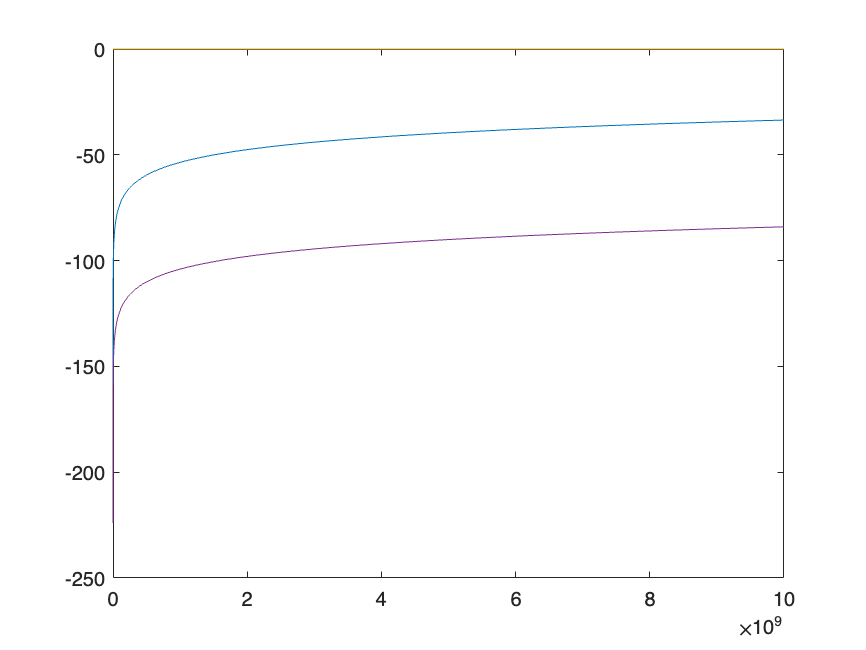

[A11, A12, A21, A22] = build_A(gamma, l, sqrt(L0/C2));

figure;
plot(f, 20*log10(abs(A11)))
hold on
plot(f, 20*log10(abs(A12)))
hold on
plot(f, 20*log10(abs(A21)))
hold on
plot(f, 20*log10(abs(A22)))
hold off

Build S parameters

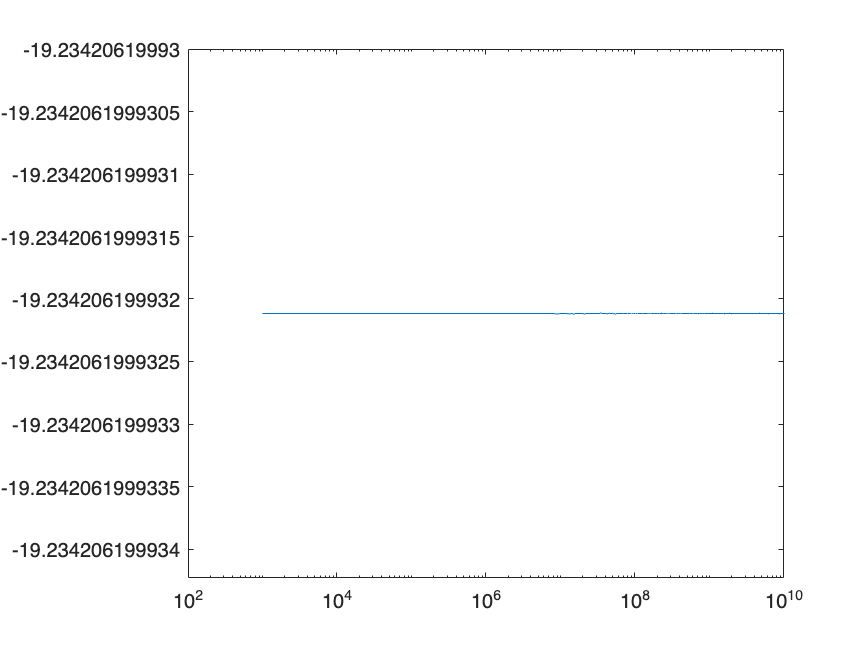

[S11, S12, S21, S22] = abcd2s(A11, A12, A21, A22, sqrt(L0/C2));
figure;
grid("on")
%semilogx(f, 20*log10(abs(S11)))
%hold on
semilogx(f, 20*log10(abs(S12)))

%hold on
%semilogx(f, 20*log10(abs(S21)))
%hold on
%semilogx(f, 20*log10(abs(S22)))
%hold off

function new_Z_load = update_Z_load(f, L0, C, Z_load)
    new_Z_load = Z_load./(f.*Z_load*C+1) + 2*1j*f*L0;
end

function [A11, A12, A21, A22] = build_A(gamma, l, Z0)
A11 = Z0.*sinh(gamma*l);
A12 = cosh(gamma*l);
A21 = A12;
A22 = (1./Z0).*sinh(gamma*l);
end

function [S11, S12, S21, S22] = abcd2s(A11, A12, A21, A22, Z0)
    S11 = A11 + A12/Z0 + A21*Z0 + A22;
    S12 = 2*(A11.*A22 - A12.*A21)./ (A11 + A12/Z0 + A21*Z0 + A22);
    S21 = 2./ (A11 + A12/Z0 + A21*Z0 + A22);
    S22 = -A12 + A11/Z0 - A21*Z0 + A22;
end